# Stock Data - FRED Datafeed

In this exercise, you will retrieve data for the London Interbank Offered Rate (LIBOR) from the FRED datafeed. This data will be returned as a structure. You will extract the relevant data, remove missing values and finally convert it into a format that can be plotted and compared to similar LIBOR rates.

## 1.

Load data from `benchmarkData.mat`.

load benchmarkData.mat

## 2.

Extract the first and the last date from `Date`in `benchmark` into two separate scalar variables. 

startDate = benchmark.Date(1)

startDate = datetime
   06-Apr-2006

endDate = benchmark.Date(end)

endDate = datetime
   02-May-2011

## 3.

Use the `fred`function to open a connection to the FRED datafeed. Retrieve data for the LIBOR 12 month rate (seriesID: USD12MD156N) for the same period of time as the benchmark data. **Hint:**Use the `fetch `function.

c = fred;
series = 'USD12MD156N';
LIB12 = fetch(c, series, startDate, endDate)

LIB12 = struct with fields:
                 Title: ' 12-Month London Interbank Offered Rate (LIBOR), based on U.S. Dollar'
              SeriesID: ' USD12MD156N'
                Source: ' ICE Benchmark Administration Limited (IBA)'
               Release: ' ICE Libor Rates (Not a Press Release)'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Daily'
                 Units: ' Percent'
             DateRange: ' 1986-01-02 to 2018-08-17'
           LastUpdated: ' 2018-08-24 7:01 AM CDT'
                 Notes: ' The data series is lagged by one week due to an agreement with the source. London Interbank Offered Rate is the average interest rate at which leading banks borrow funds of a sizeable amount from other banks in the London market. Libor is the most widely used "benchmark" or reference rate for short term interest rates  In consideration for ICE Benchmark Administration Limited ("IBA") coordinating and the Libor Contributor Banks supplying the data from

close(c)

## 4. 

Use dot notation to extract the `Data`field from the resultant structure variable and remove any missing values using `rmmissing`.

LIB12allData = LIB12.Data;
LIB12clean = rmmissing(LIB12allData)

LIB12clean = 	1.0e+05 *

    7.3277    0.0001
    7.3277    0.0001
    7.3278    0.0001
    7.3278    0.0001
    7.3278    0.0001
    7.3278    0.0001
    7.3278    0.0001
    7.3279    0.0001
    7.3279    0.0001
    7.3279    0.0001


## 5.

Separate the dates (column 1) and data (column 2) into two column vectors and convert the dates from datenumformat in to datetime.

LIB12data = LIB12clean(:,2)

LIB12data =     5.2894
    5.2950
    5.3506
    5.3406
    5.3300
    5.3606
    5.3356
    5.2800
    5.3094
    5.3288


LIB12dates = LIB12clean(:,1);
% convert to datetime
LIB12dates = datetime(LIB12dates, 'ConvertFrom', 'datenum')

LIB12dates = 1279×1 datetime array
   06-Apr-2006 00:00:00
   07-Apr-2006 00:00:00
   10-Apr-2006 00:00:00
   11-Apr-2006 00:00:00
   12-Apr-2006 00:00:00
   13-Apr-2006 00:00:00
   18-Apr-2006 00:00:00
   19-Apr-2006 00:00:00
   20-Apr-2006 00:00:00
   21-Apr-2006 00:00:00
   24-Apr-2006 00:00:00
   25-Apr-2006 00:00:00
   26-Apr-2006 00:00:00
   27-Apr-2006 00:00:00
   28-Apr-2006 00:00:00
   02-May-2006 00:00:00
   03-May-2006 00:00:00
   04-May-2006 00:00:00
   05-May-2006 00:00:00
   08-May-2006 00:00:00
   09-May-2006 00:00:00
   10-May-2006 00:00:00
   11-May-2006 00:00:00
   12-May-2006 00:00:00
   15-May-2006 00:00:00
   16-May-2006 00:00:00
   17-May-2006 00:00:00
   18-May-2006 00:00:00
   19-May-2006 00:00:00
   22-May-2006 00:00:00
   23-May-2006 00:00:00
   24-May-2006 00:00:00
   25-May-2006 00:00:00
   26-May-2006 00:00:00
   30-May-2006 00:00:00
   31-May-2006 00:00:00
   01-Jun-2006 00:00:00
   02-Jun-2006 00:00:00
   05-Jun-2006 00:00:00
   06-Jun-2006 00:00:00
   07

## 6.

Plot the LIBOR 12 month rate against the date. Add lines for the LIBOR 3 month rate and LIBOR 1 month rate from the `benchmark`table to the same plot and annotate.

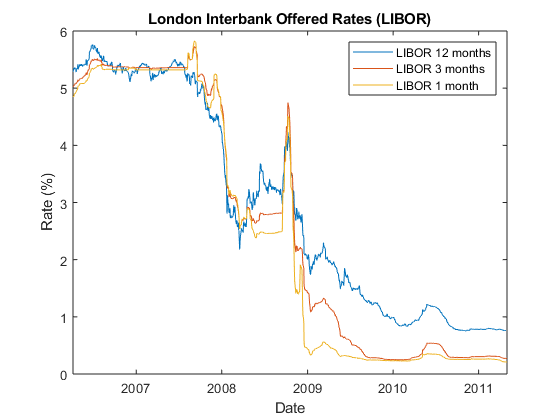

plot(LIB12dates, LIB12data)
hold on
plot(benchmark.Date, benchmark.LIB3M)
plot(benchmark.Date, benchmark.LIB1M)
hold off
xlabel('Date')
ylabel('Rate (%)')
title('London Interbank Offered Rates (LIBOR)')
legend('LIBOR 12 months', 'LIBOR 3 months', 'LIBOR 1 month')